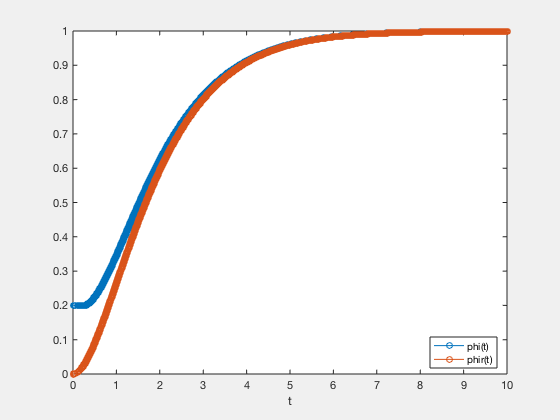

clear variables
syms x th [3 1]
syms u ur
b = 1;
c = 1;
% x1=phi, x2=omega; x3=t
f(x1,x2,x3,u) = [x2;-c*x2*abs(x2)+u;1];
% th1=phir, th2=phirdot,th3=t
fr(th1,th2,th3,ur) = [th3*exp(-th3)*1;(1-th3)*exp(-th3)*1;1];
r = th1;
rdot = th2;
u_fbl = exp(-x3)*1-x2-(1.5*x2*x2+1)*sign(x1+x2-r-rdot);
syms t
F = matlabFunction([f(x1,x2,x3,u_fbl);fr(th1,th2,th3,ur)], ...
    'Vars',{t,[x1;x2;x3;th1;th2;th3],ur});
ur_steps = @(t)(t>=1)-2*(t>=4)+3*(t>=7);
X0 = [0.2;0;0;0;0;0];
tf = 10;
options = odeset('OutputSel',[1,4]);
ode45(@(t,x)F(t,x,ur_steps(t)),[0,tf],X0,options);
xlabel('t')
legend('phi(t)','phir(t)','location','best')